clear all;

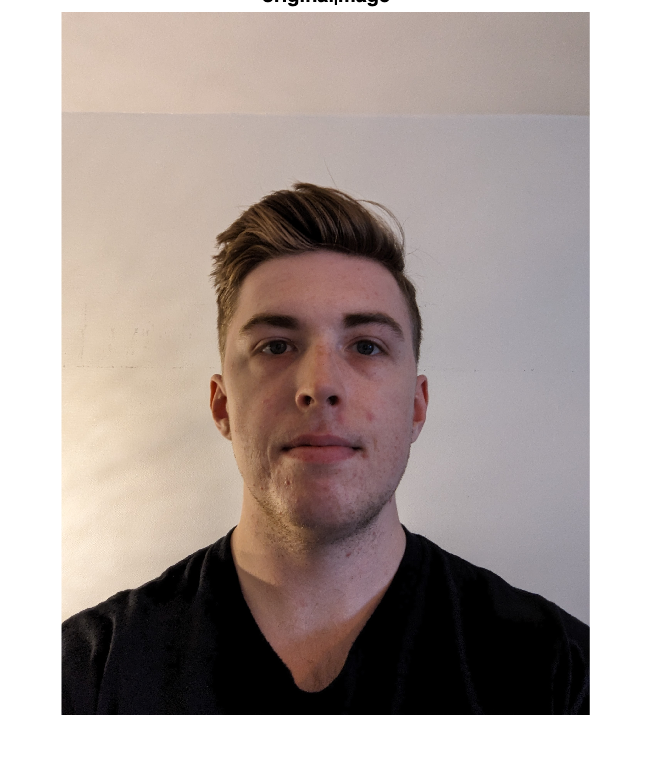

% read image

original_image = imread('me.jpg');
gray_image = im2gray(original_image);

imshow(original_image)
title('original_image')

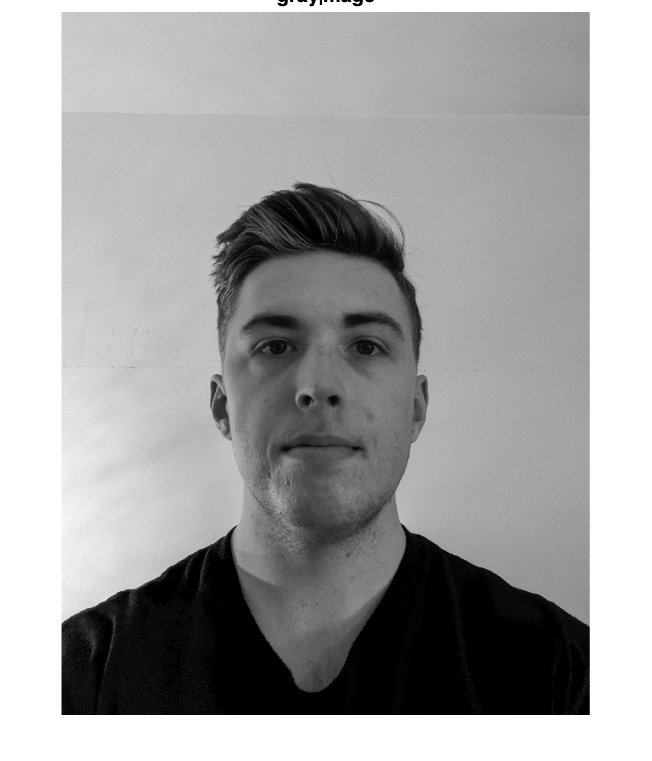

imshow(gray_image)
title('gray_image')


gray_image = double(gray_image);

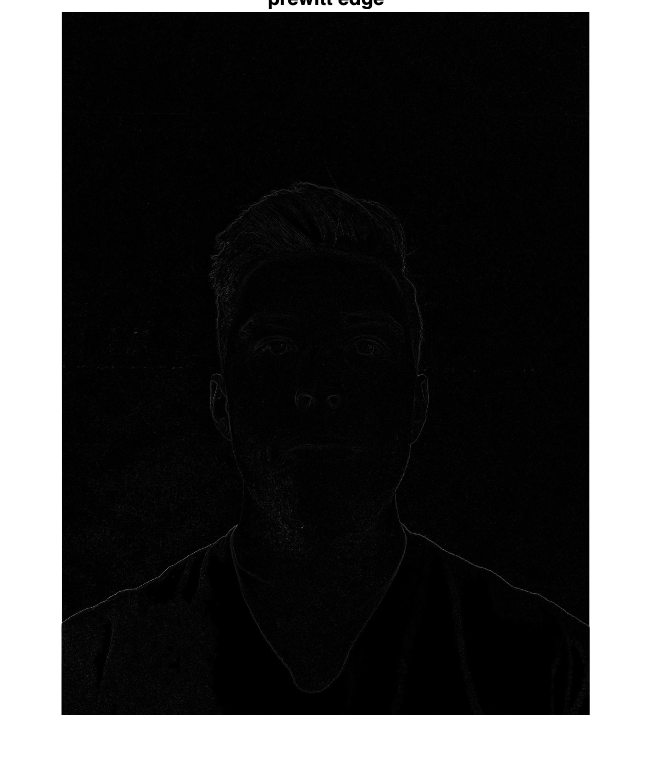

% edge detection using prewitt/scharr kernel

prewitt_kernel=[-1 0 1; -1 0 1; -1 0 1];
scharr_kernel=[-3 0 3; -10 0 10; -3 0 3];

p_x=conv2(gray_image, prewitt_kernel, 'same');
p_y=conv2(gray_image, prewitt_kernel', 'same');
prewitt_edge=sqrt(p_x.^2 + p_y.^2);
prewitt_edge = uint8(mat2gray(prewitt_edge) * 255.);

s_x=conv2(gray_image, scharr_kernel, 'same');
s_y=conv2(gray_image, scharr_kernel', 'same');
scharr_edge=sqrt(s_x.^2 + s_y.^2);
scharr_edge = uint8(mat2gray(scharr_edge) * 255.);

imshow(abs(prewitt_edge), [])
title('prewitt edge')

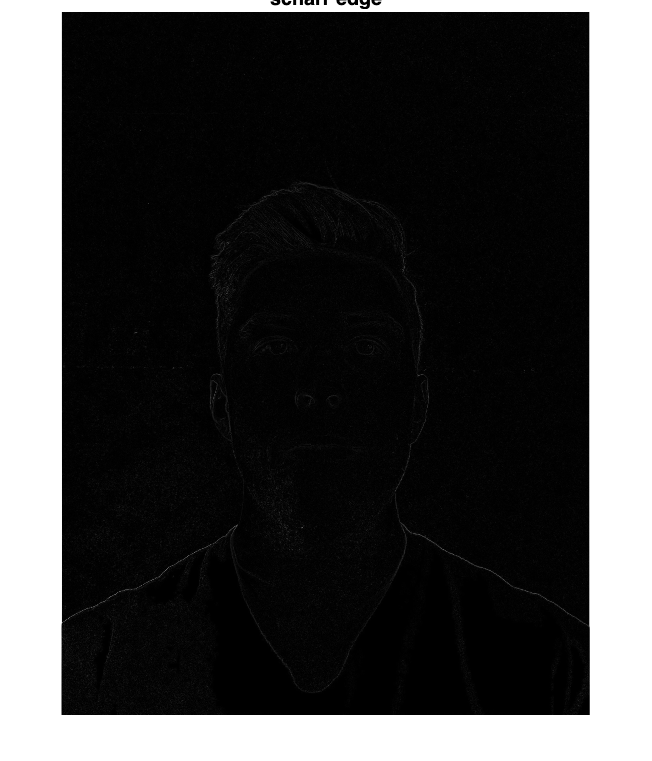

imshow(abs(scharr_edge), [])
title('scharr edge')



[min,max] = bounds(scharr_edge,"all");


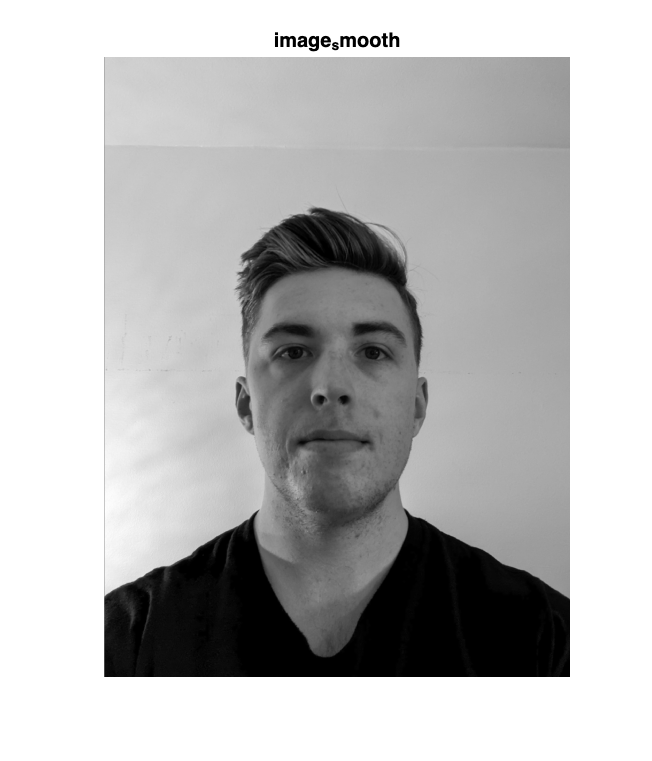

% smooth the image

average_filter = fspecial('average',7); 
image_smooth = filter2(average_filter, gray_image); 

imshow(image_smooth, [], "InitialMagnification", 'fit');
title('image_smooth')


[minS,maxS] = bounds(image_smooth,"all");


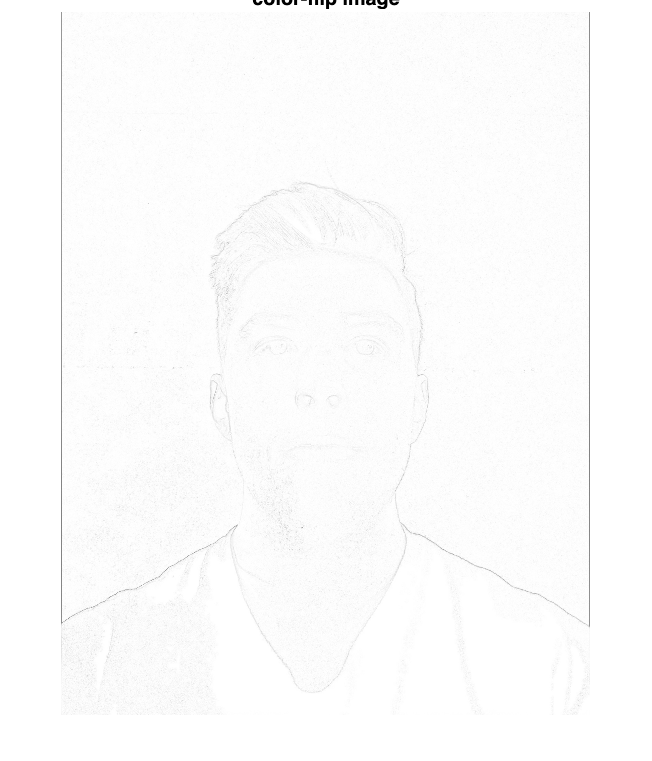

% take only the edge

flip_image = scharr_edge;

for i = 1:size(gray_image, 1)
    for j = 1:size(gray_image, 2)     
        flip_image(i, j) = (255. - scharr_edge(i, j));
    end
end
[minA,maxA] = bounds(flip_image,"all");

imshow(flip_image, [])
title('color-flip image')


% white = 255, black = 0

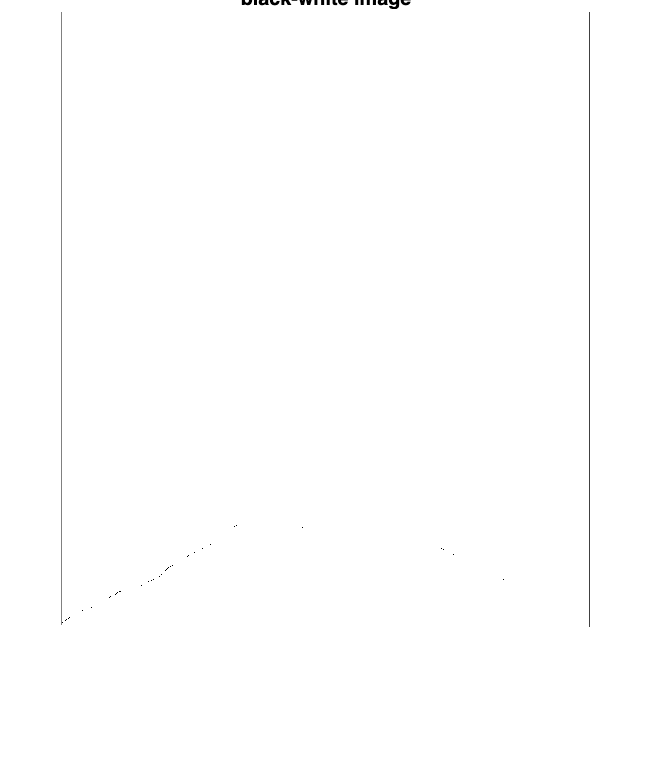

% apply threshold

bw_image = zeros(size(gray_image));

for i = 1:size(gray_image, 1)
    for j = 1:size(gray_image, 2)
        if flip_image(i, j) >= 180
            bw_image(i, j) = 255;
        else
            bw_image(i, j) = 0;
        end
    end
end

imshow(bw_image, [])
title('black-white image')

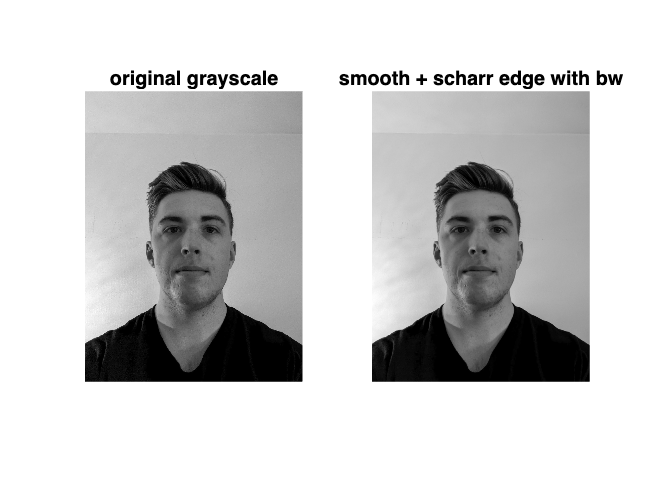

% add the bw_image on the smooth image

edit_bw_image = zeros(size(gray_image));

for i = 1:size(gray_image, 1)
    for j = 1:size(gray_image, 2)
        if bw_image(i, j) == 0
            edit_bw_image(i, j) = image_smooth(i, j) + bw_image(i, j);
        else
            edit_bw_image(i, j) = image_smooth(i, j);
        end
    end
end

figure;
subplot(1, 2, 1);
imshow(gray_image, [])
title('original grayscale')
subplot(1, 2, 2);
imshow(edit_bw_image, [])
title('smooth + scharr edge with bw')

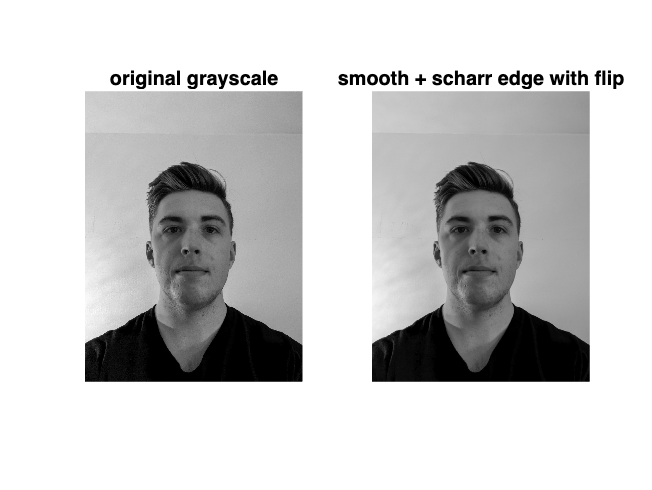

% add the scharr edge on the smooth image

edit_flip_image = zeros(size(gray_image));

for i = 1:size(gray_image, 1)
    for j = 1:size(gray_image, 2)
        if flip_image(i, j) >= 150
            edit_flip_image(i, j) = image_smooth(i, j);
        else
            edit_flip_image(i, j) = image_smooth(i, j) + flip_image(i ,j);
        end
    end
end

figure;
subplot(1, 2, 1);
imshow(gray_image, [])
title('original grayscale')
subplot(1, 2, 2);
imshow(edit_flip_image, [])
title('smooth + scharr edge with flip')